# Exercicis Bucles

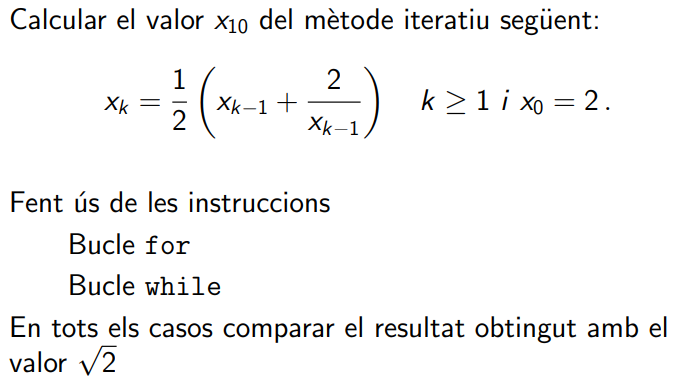

Mediante el uso de un for:

clear vars;         % clean el workspace
k = 10;             % num de iteraciones
xk = zeros(k+1,1);  % allocation
xk(1) = 2;          % valor inicial

for i = 2:size(xk)
    xk(i) = 0.5 * (xk(i-1) + 2/xk(i-1));
end

Calculamos los errores:

[ea, er, ~] = funerror(xk, sqrt(2));

array2table([(0:k)', xk, ea, er], 'VariableNames', {'k', 'xk', 'ea', 'er'} )

ans = 11×4 table
    k       xk          ea            er    
    __    ______    __________    __________

     0         2       0.58579       0.41421
     1       1.5      0.085786       0.06066
     2    1.4167     0.0024531     0.0017346
     3    1.4142    2.1239e-06    1.5018e-06
     4    1.4142    1.5947e-12    1.1276e-12
     5    1.4142    2.2204e-16    1.5701e-16
     6    1.4142    2.2204e-16    1.5701e-16
     7    1.4142    2.2204e-16    1.5701e-16
     8    1.4142    2.2204e-16    1.5701e-16
     9    1.4142    2.2204e-16    1.5701e-16
    10    1.4142    2.2204e-16    1.5701e-16


Mediante el uso de un while:

clear vars;         % clean el workspace
k = 10;             % num de iteraciones
xk = zeros(k+1,1);  % allocation
xk(1) = 2;          % valor inicial

i = 2;
while i <= k
    xk(i) = 0.5 * (xk(i-1) + 2/xk(i-1));
    i = i + 1;
end

Calculamos los errores:

[ea, er, ~] = funerror(xk, sqrt(2));

array2table([(0:k)', xk, ea, er], 'VariableNames', {'k', 'xk', 'ea', 'er'} )

ans = 11×4 table
    k       xk          ea            er    
    __    ______    __________    __________

     0         2       0.58579       0.41421
     1       1.5      0.085786       0.06066
     2    1.4167     0.0024531     0.0017346
     3    1.4142    2.1239e-06    1.5018e-06
     4    1.4142    1.5947e-12    1.1276e-12
     5    1.4142    2.2204e-16    1.5701e-16
     6    1.4142    2.2204e-16    1.5701e-16
     7    1.4142    2.2204e-16    1.5701e-16
     8    1.4142    2.2204e-16    1.5701e-16
     9    1.4142    2.2204e-16    1.5701e-16
    10         0        1.4142             1


### MISMO EJERCICIO, PERO UTILIZANDO COMO CONDICION LA TOLERANCIA

Mediante el uso de un while:

clear vars;             % clean el workspace

itmax = 10;                             % num de iteraciones maximo
tolmax = 0.5e-10;    % tolerancia que admitimos

xk = zeros(itmax+1,1);  % allocation
xk(1) = 2;              % valor inicial

i = 2; tol = funerror(2, sqrt(2));
while tol > tolmax && i <= itmax
    xk(i) = 0.5 * (xk(i-1) + 2/xk(i-1));
    tol = funerror(xk(i), sqrt(2));
    i = i + 1;
end
xk = xk(1:i-1);

Calculamos los errores:

[ea, er, ~] = funerror(xk, sqrt(2));

array2table([(0:i-2)', xk, ea, er], 'VariableNames', {'k', 'xk', 'ea', 'er'} )

ans = 5×4 table
    k      xk          ea            er    
    _    ______    __________    __________

    0         2       0.58579       0.41421
    1       1.5      0.085786       0.06066
    2    1.4167     0.0024531     0.0017346
    3    1.4142    2.1239e-06    1.5018e-06
    4    1.4142    1.5947e-12    1.1276e-12


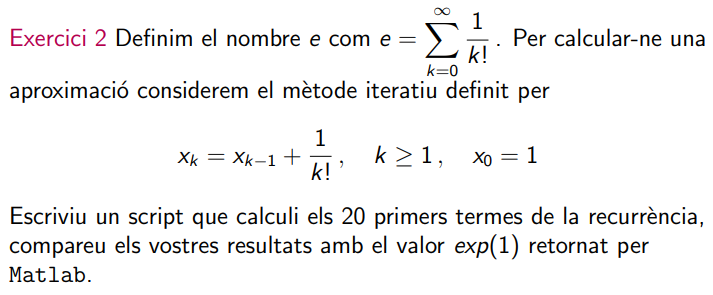

clear vars;          % clean el workspace
itmax = 10;          % num de iteraciones maximo
tolmax = 0.5e-10;    % tolerancia que admitimos


%% HACERç